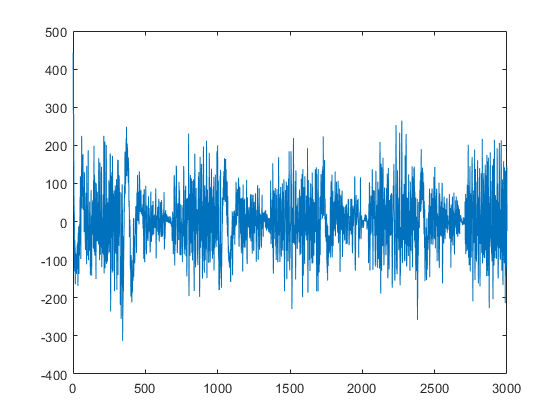

%% EMG signal processing
close all
clear all

% addpath('Z:\UNAIR\STUDY\SKRIPSI\DATA\DATA_odi2kg_(6.2)2019_10_1_2999');
% filename('DATA_odi2kg_(6.2)2019_10_1_2999.csv')

%% Step1 : Read Data from .txt tile
fq = 25; %sampling frequency
loc='Z:\UNAIR\STUDY\SKRIPSI\DATA\DATA_odi2kg_(6.2)2019_10_1_2999';
data1 = csvread([loc '\' 'DATA_odi2kg_(6.2)2019_10_1_2999.csv'],1,1);
%% Filtering using butterworth filter of order 4
% High-pass filter
filt1 = fdesign.highpass('n,f3db',4,2*10*(1/1000)); %high-pass filter, cut off frequency at 10Hz, sampling frequency of 1kHz
H1 = design(filt1,'butter');
highpass_EMG = filter(H1, data1(:,7)); % sampling frequency of 1kHz
% Low-pass filter
filt2 = fdesign.lowpass('n,f3db',4,2*500*(1/1000)); %low-pass filter, cut off frequency at 500Hz
H2 = design(filt2,'butter');
lowpass_EMG = filter(H2,highpass_EMG);
% Notch Filter (50Hz)
filt3 = fdesign.notch(4,0.05,10); %notch filter (50Hz)
H3 = design(filt3);
cleaned_EMG = filter(H3,lowpass_EMG);
figure(1);plot(cleaned_EMG);

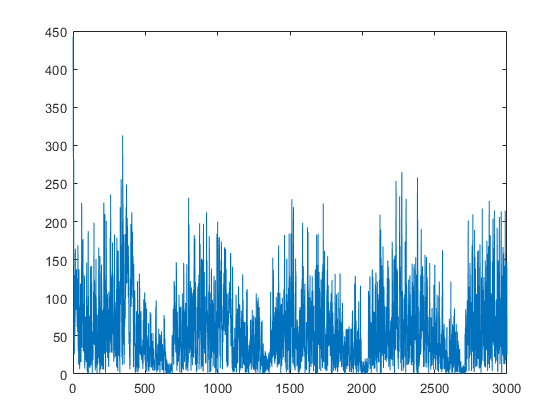


%%rectified
remg=abs(cleaned_EMG);
figure(2); plot(remg);

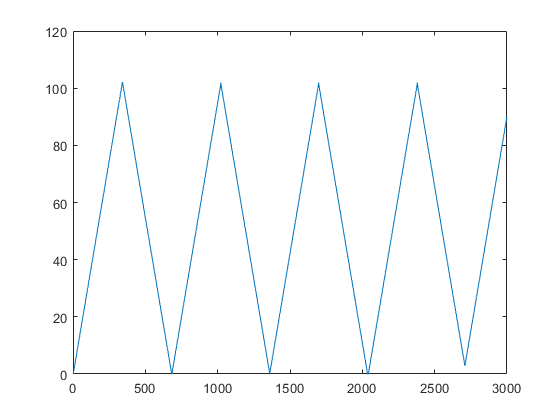


sudut=data1(:,6);
plot(sudut);

tim=data1(:,4);
tmax=max(tim);
tmin=min(tim);
[n c]=size(tim);
ts=n/(tmax-tmin);
for i=1:n
    t(i)=(i-1)*ts;
end
%addpath('C:\Users\yusuf\OneDrive\Dokumen\MATLAB');

%%ARX
U=iddata(sudut,remg,ts);
T=arx(U,[4,4,1])


T =
Discrete-time ARX model:  A(z)y(t) = B(z)u(t) + e(t)                     
  A(z) = 1 - 0.9819 z^-1 - 0.007225 z^-2 - 0.6598 z^-3 + 0.65 z^-4       
                                                                         
  B(z) = 0.0006605 z^-1 + 0.000112 z^-2 - 6.284e-05 z^-3 + 0.0004393 z^-4
                                                                         
Sample time: 0.13033 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                         
Estimated using ARX on time domain data "U".    
Fit to estimation data: 98.6% (prediction focus)
FPE: 0.1659, MSE: 0.1646                        


H=tf(T);
G=H(1)


G =
 
  From input "u1" to output "y1":
  0.0006605 z^-1 + 0.000112 z^-2 - 6.284e-05 z^-3 + 0.0004393 z^-4
  ----------------------------------------------------------------
     1 - 0.9819 z^-1 - 0.007225 z^-2 - 0.6598 z^-3 + 0.65 z^-4
 
Sample time: 0.13033 seconds
Discrete-time transfer function.



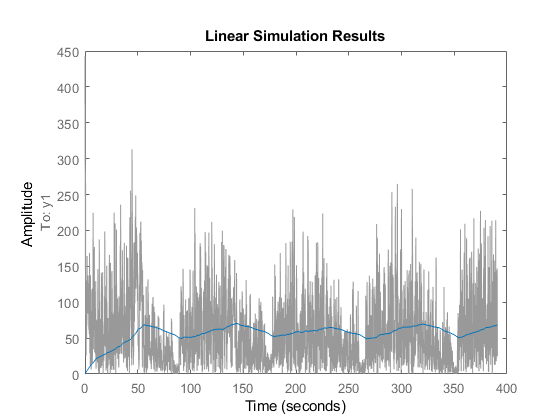

lsim(G,remg,t')

%hold on, plot(t',sudut,'o',t',y,'.-')

% 
% figure; 
% plot(data1(:,4), data1(:,7)-mean(data1(:,7))); 
% xlabel('Time/s','fontsize', 14); ylabel('Signal magnitude', 'fontsize', 14); 
% title('Raw Data from EMG - Biceps 1', 'fontsize', 14);set(gca,'FontSize',14);
% 
% %% Step2: Perform Fast Fourier Transform and Shift Zero-component to center
% % Biceps 1
% sEMG1 = data1(:,5); 
% fft_sEMG1 = fft(sEMG1); 
% fft_sEMG1 = fftshift(fft_sEMG1);
% n = length(sEMG1);  
% fq_axis1 = (-n/2:n/2-1)*fq/n; % zero-centered frequency range
% abs_fft_sEMG1 = abs(fft_sEMG1);
% figure; 
% plot(fq_axis1, abs_fft_sEMG1 ); axis([fq_axis1(1) fq_axis1(end) 0 1000]); 
% xlabel('Frequency/Hz','fontsize', 14); ylabel('X(jw) magnitude','fontsize', 14); 
% title('Frequency Domain - Biceps 1','fontsize', 14);
% set(gca,'FontSize',14);
% 
% %% Step 3: Generate Bandpass filter 
% % can change to your desired cutoff frequency
% highpass = 5;   
% lowpass = 10;    
% 
% % get the index of -10 to -5 and 5 to 10Hz. 
% cutoff1 = ceil((12.5-highpass)/(fq/length(sEMG1))); cutoff2 = ceil((12.5-lowpass)/(fq/length(sEMG1)));
% cutoff3 = ceil((highpass+12.5)/(fq/length(sEMG1))); cutoff4 = ceil((lowpass+12.5)/(fq/length(sEMG1)));
% 
% sEMG1 = data1(:,7); 
% H = zeros(length(sEMG1),1);
% H(cutoff2:cutoff1) = 1; % take only the -10 to -5Hz
% H(cutoff3:cutoff4) = 1; % take only the 5 to 10Hz
% 
% figure; plot(fq_axis1, H); set(gca,'YLim',[0 2]); xlabel('Freqeuncy/Hz','fontsize', 14); ylabel('Amplitude','fontsize', 14);
% title('Bandpass filter','fontsize', 14);set(gca,'FontSize',14);
% 
% %% Step 4: Perform Bandpass filter, inverse shifting and inverse Fourier transform
% % Biceps 1
% cutoff1 = ceil((12.5-highpass)/(fq/length(sEMG1))); cutoff2 = ceil((12.5-lowpass)/(fq/length(sEMG1)));
% cutoff3 = ceil((highpass+12.5)/(fq/length(sEMG1))); cutoff4 = ceil((lowpass+12.5)/(fq/length(sEMG1)));
% H = zeros(length(sEMG1),1); H(cutoff2:cutoff1) = 1; % take only the -10 to -5Hz
% H(cutoff3:cutoff4) = 1; % take only the 5 to 10Hz
% 
% yt1 = ifftshift(fft_sEMG1.*H); 
% yt1 = ifft(yt1);
% t = 1/fq*(1:length(yt1));
% figure;
% plot(t, real(yt1),'r');xlabel('Time/s','fontsize', 14); ylabel('Amplitude','fontsize', 14); 
% title('Signal after bandpass filter - Biceps 1','fontsize', 14);set(gca,'FontSize',14);
% 
% %% Step 5: Feature extraction - MAV using convolution. 
% dt = 2*fq; % hand flex for 2 sec; 
% dt_5 = 5*fq;   % subject flex at 5s, 10s,15s, 20s, 25s, 30s.
% wind = 2*fq;
% filter = ones(20,1);
% filter = filter/length(filter);
% 
% % Biceps 1 
% MAV1 = zeros(length(yt1),1);
% var1 = zeros(length(yt1),1);
% MAV1 = conv(abs(real(yt1)),filter,'same');
% 
% %% Step 6: K-mean clustering
% n = 10; %clustering window
% 
% for i = 1:length(MAV1)-n
%     X1(i,:) =  MAV1(i:i+n);
% end
% [idx1,C1] = kmeans(X1,2);
% 
% 
% % theorectical response and adjusting
% dt_r = 0.04;
% t_response = [0:dt_r:35]';
% response = zeros(size(t_response));
% START = 5/dt_r;
% dt_r2 = 2/dt_r;
% dt_r5 = 5/dt_r;
% response(START+1:START+dt_r2,1) = 1;
% response(2*START+1:2*START+dt_r2,1) = 1;
% response(3*START+1:3*START+dt_r2,1) = 1;
% response(4*START+1:4*START+dt_r2,1) = 1;
% response(5*START+1:5*START+dt_r2,1) = 1;
% response(6*START+1:6*START+dt_r2,1) = 1;
% 
% figure;
% plot(data1(:,1),MAV1,'linewidth',2); hold on; 
% plot(data1(:,1),real(yt1),'r'); 
% plot(data1(:,1),[zeros(ceil(n/2),1);idx1;zeros(floor(n/2),1)],'k', 'linewidth', 2); 
% plot(t_response(:,1),response,'g--','linewidth',3);
% legend('MAV','EMG signal','Contract(Min); Relax (Max)', 'True response', 'location', 'Northeast');
% xlabel('Time/s'); ylabel('Signal Amplitude'); title('Biceps 1'); grid on;
% axis([0 round(max(data1(:,1))) min(real(yt1)) max(real(yt1))]);
% set(gca,'FontSize',14);